clear
filepath = 'D:\工作汇总\文章\散射场重构\文章\SI\图片\S6\2Dmaterials';
files = dir(fullfile(filepath,'*.*tif*'));
figure
ii = 4;
files(ii).name

ans = 'SnSe2.tiff'

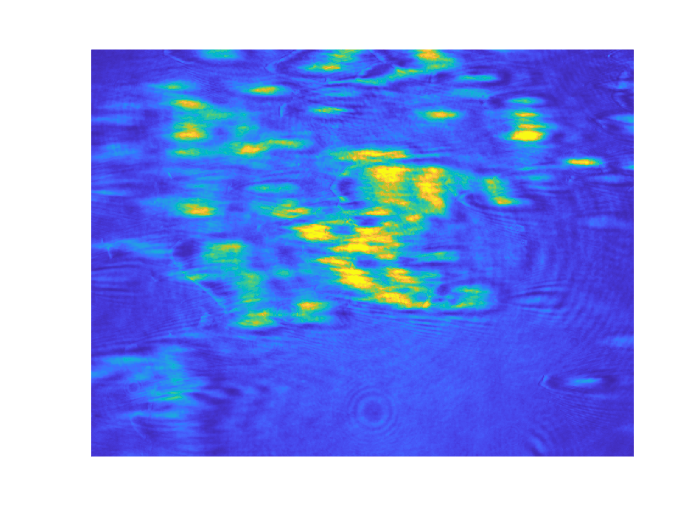

I = double(imread(fullfile(filepath,files(ii).name)));
[m,n] = size(I);
[x1,y1] = meshgrid(1:n,1:m);
[x2,y2] = meshgrid(1:0.5:n,1:0.5:m);
I = interp2(x1,y1,I,x2,y2);

imagesc(I)
axis off
axis equal

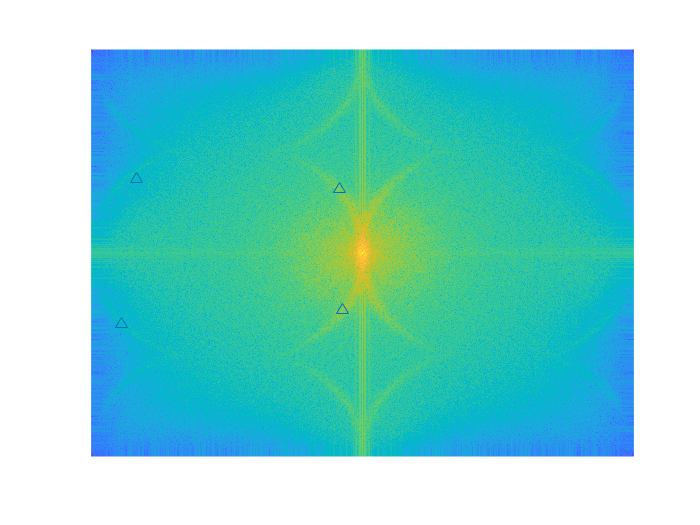

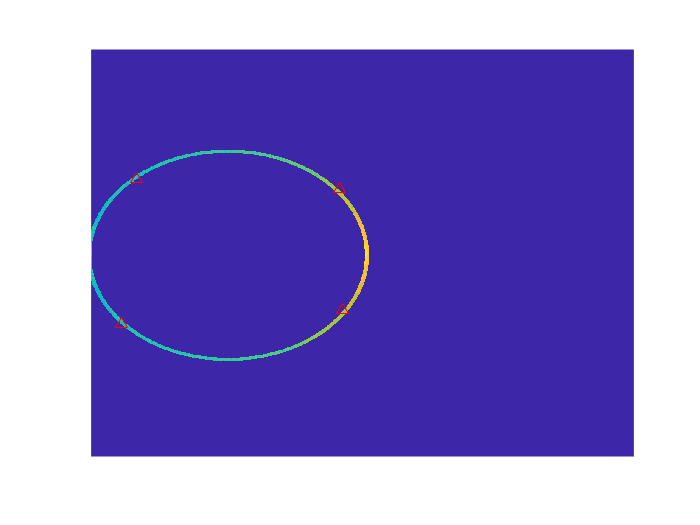

colormap(sunglow)

F = fftshift(fft2(ifftshift(I)));
[center_raw,center_col,R,~] = findcircle(log(abs(F)),5,0,0);

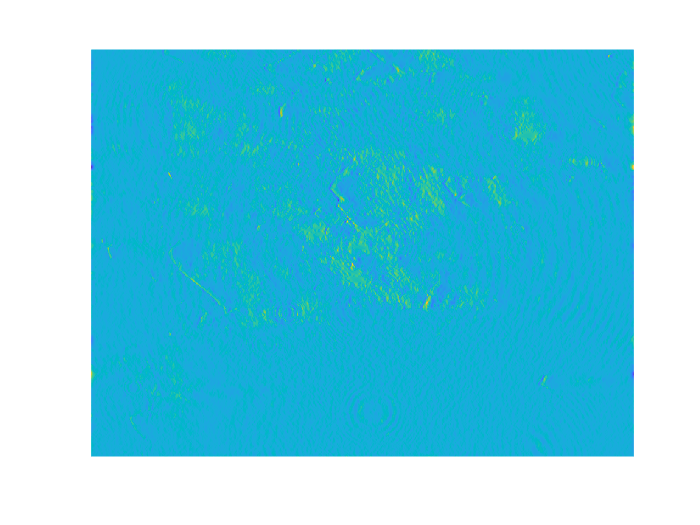

peaks = [center_col,center_raw,R];

mask = EwaldMask(F,peaks,0.15,'G',2,'in');
I_rcn = fftshift(ifft2(ifftshift(F.*mask)));

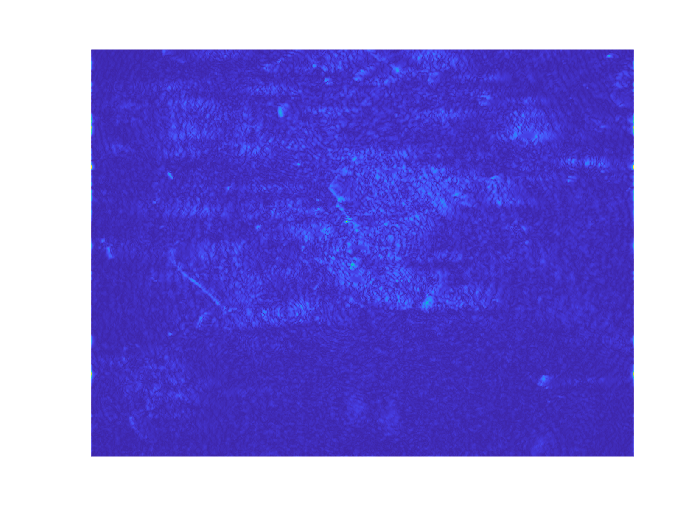

figure
imagesc(abs(I_rcn))
axis off
axis equal

colormap(sunglow)
